# 第5章 数字滤波器结构

## 5.5 脉冲响应不变变换法

### 5.5.5 用脉冲响应不变变换法设计数字巴特渥斯滤波器

#### `Ch5_5_1`

用脉冲响应不变变换法设计数字巴特渥斯滤波器

要求其指标为：

在$0\ldotp 2\pi \le \omega$的通带范围内幅度特性变化（下降) 小于 1 dB

在$0\ldotp 3\pi \le \omega \le \pi$的阻带范围内，衰减大于15 dB

实现上述滤波器

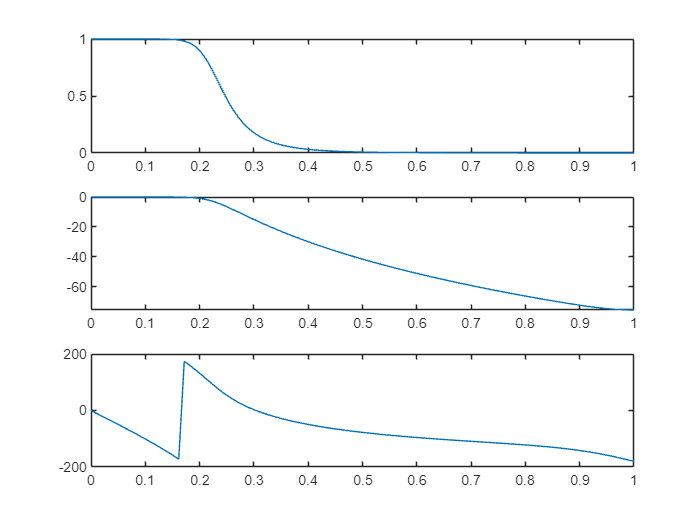

% 指标
T = 1;
fs = 1;
Wp = 0.2*pi; 
Ws = 0.3*pi;
Ap = 1; %dB
As = 15; %dB
% 模拟原型滤波器
[N,Wc] = buttord(Wp,Ws,Ap,As,'s'); 
[z,p,k] = buttap(N);
[num,den] = zp2tf(z,p,k);
% 数字滤波器
[B,A] = butter(N,Wc,'s');
[D,C] = impinvar(B,A,fs);
W = linspace(0,pi); 
H = freqz(D,C,W);
mag = abs(H)/abs(H(1));
dbmag = 20*log10(mag);
phase = angle(H); 
degphase = phase*180/pi; 
subplot(3,1,1), plot(W/pi,abs(H));
subplot(3,1,2), plot(W/pi,dbmag);
subplot(3,1,3), plot(W/pi,degphase);